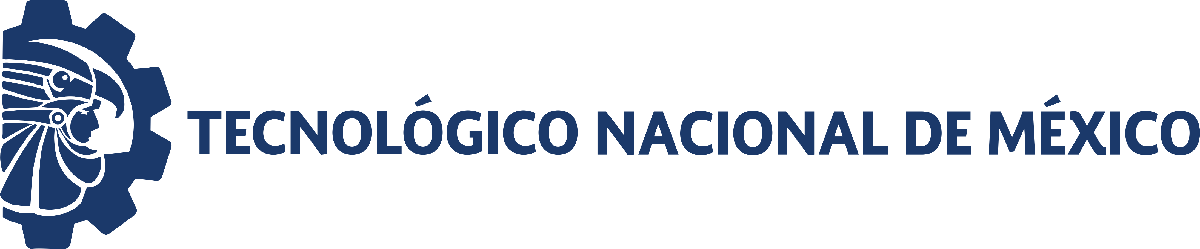                                 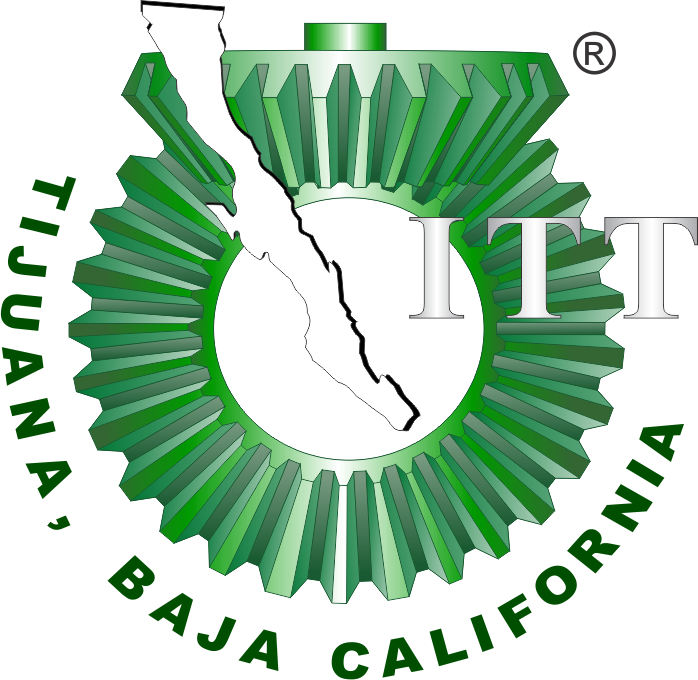

# Práctica cuatro: Regeneracion de globulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

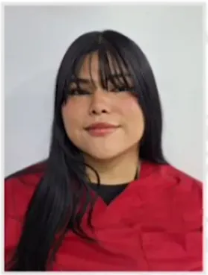

Nombre del alumno: **Paola Gonzalez Sanchez**

Número de control: **22211757**

Correo institucional: **L22211757@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all'); close all; 

tend = 180; %tiempo de simulación en días
dt = 1E-3; %intervalo de integración para el método de solución por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el método numérico 
% Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885; 
% Parámetros particulares para cada paciente 

gamma = [0.769, 0.388, 0.510, 0.590, 0.262, 0.324, 0.356, 0.089, 0.243, 0.057];
beta = [1.650, 0.867, 1.617, 2.615, 1.518, 2.676, 0.891, 2.557, 0.925, 0.879];

% Intervalo de las condiciones iniciales
xmin = 0.95; xmax= 1.05;
seed = 22211757; %Semilla para asegurar reproducibilidad
rng(seed, 'twister');
interval = xmin + (xmax - xmin).*rand(1,numel(gamma));

% Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1_0 = '); disp(x1_0);...
x2_0 = x2_0*interval; disp('x2_0 = '); disp(x2_0);...
x3_0 = x3_0*interval; disp('x3_0 = '); disp(x3_0);

x1_0 = 
   60.4604   61.1162   57.7565   56.0959   60.0087   58.6998   61.0280   61.8326   57.3281   59.8023



x2_0 = 
   45.0891   45.5782   43.0726   41.8342   44.7523   43.7761   45.5124   46.1124   42.7532   44.5983



x3_0 = 
  906.9053  916.7429  866.3471  841.4388  900.1310  880.4969  915.4203  927.4885  859.9213  897.0342



## Caso:Sin transfusion sanguinea 

u = zeros(n+1, 1);
fig = 1; 
for i = 1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i), beta(i),gamma(i),u,dt,tend); 
    plotdata (t,x1,x2,x3,fig)
end

## Caso: Con transfusion sanguinea

u = zeros(n+1, 1); u (1:1/dt)=1;
fig = 2; 
for i = 1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i), beta(i),gamma(i),u,dt,tend); 
    plotdata (t,x1,x2,x3,fig)
end

## Funciones

## Modelo matemático

- 

- 

- 

function [t, x1, x2,x3] = system(x1_0, x2_0, x3_0, beta, gamma, u, dt,tend)
    %parámetros fijos
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x1 = zeros(n+1, 1); x1(1) = x1_0;
    x2 = zeros(n+1, 1); x2(1) = x2_0;
    x3 = zeros(n+1, 1); x3(1) = x3_0;

    for i =1: n 
        x1(i+1) =x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base-x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1) =x2(i) + (beta*(k1*x1(i) - k2*x2(i)))*dt;
        x3(i+1) =x3(i) + (beta*(k2*x2(i)- alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end

### Soluciones en el tiempo.

function plotdata(t, x1,x2,x3,fig)
    set(figure(fig), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,20,20]);

    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

   
    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x1); 
    xlabel('$t$ $[days]$', 'Interpreter','latex', 'FontSize', 10);
    ylabel('$x_1(t)$', 'Interpreter','latex', 'FontSize', 10);
    xlim([0 180]); xticks(0:15:180);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    L = legend ('Patient 1' , 'Patient 2' , 'Patient 3' , 'Patient 4' , 'Patient 5',...
        'Patient 6' , 'Patient 7' , 'Patient 8' , 'Patient 9' , 'Patient 10');
    set(L, 'FontSize', 9,'Box', 'Off', 'Location', 'NorthEastOutside');

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x2); 
    xlabel('$t$ $[days]$', 'Interpreter','latex', 'FontSize', 10);
    ylabel('$x_2(t)$', 'Interpreter','latex', 'FontSize', 10);
    xlim([0 180]); xticks(0:15:180);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    L = legend ('Patient 1' , 'Patient 2' , 'Patient 3' , 'Patient 4' , 'Patient 5',...
        'Patient 6' , 'Patient 7' , 'Patient 8' , 'Patient 9' , 'Patient 10');
    set(L, 'FontSize', 9,'Box', 'Off', 'Location', 'NorthEastOutside');

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x3); 
    xlabel('$t$ $[days]$', 'Interpreter','latex', 'FontSize', 10);
    ylabel('$x_3(t)$', 'Interpreter','latex', 'FontSize', 10);
    xlim([0 180]); xticks(0:15:180);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    L = legend ('Patient 1' , 'Patient 2' , 'Patient 3' , 'Patient 4' , 'Patient 5',...
        'Patient 6' , 'Patient 7' , 'Patient 8' , 'Patient 9' , 'Patient 10');
    set(L, 'FontSize', 9,'Box', 'Off', 'Location', 'NorthEastOutside');

    if fig ==1
        exportgraphics(gcf, 'Caso Sin transfusion.pdf', 'ContentType', 'Vector')
    elseif fig ==2
        exportgraphics(gcf, 'Caso Con transfusion.pdf', 'ContentType', 'Vector')
    end
 
end
